## Tutorial 7: Singular value decomposition

In this Tutorial you will learn how to implement the singular value decomposition in Matlab and how to use it to compress images.

### Singular value decomposition

Recall from class that the singular value decomposition (SVD) of an *m* x *n* matrix **A** is

${\bf{A}} ={\bf{U\Sigma V}}^T$,

where the an *m *x *n* matrix 

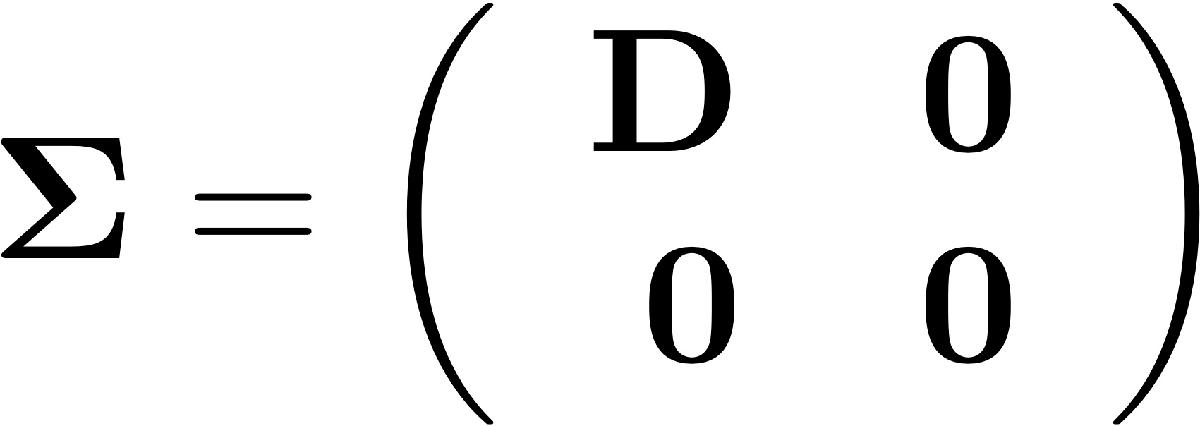

with **D** being a diagonal *r* x* r* matrix whose *r* diagonal elements are the singular values

$\sigma_1\geq \sigma_2 \geq \cdots \geq \sigma_r$,

and where **U** is a *m* x *m* orthogonal matrix (${\bf{U}}^T{\bf{U}}={\bf{I}}$), and where **V** is an *n* x *n* orthognal matrix (${\bf{V}}^T{\bf{V}}={\bf{I}}$).

In Matlab, you can compute the SVD of a matrix **A** with the command svd. Use help to find out how to use it.

help svd

Now you are ready to use it. Use the svd command to compute the svd of the matrix

A = [1 -1
    -2  2
     2 -2];
[U,S,V] = svd(A)

You can check that ${\bf{A}} ={\bf{U\Sigma V}}^T$:

A - U*S*V'

Note, as usual, the numerical error. The matrix A - U*S*V' should be equal to the zero matrix, but because of numerical error, it is a matrix with small elements.

### Reduced SVD, the pseudo inverse and low-rank approximations

Recall from class that the rank of a matrix **A** is the number of non-zero singular values. Since the zero singular values do not really contribute to **A**, one can construct a more compact singular value decomposition by skipping the zero singular values. This also means that one skips columns of **U** and **V**. For an m x n matrix with rank r, define 

${\bf{U}}_r = [{\bf{u}}_1, {\bf{u}}_2,\dots,{\bf{u}}_r]$,

${\bf{V}}_r = [{\bf{v}}_1, {\bf{v}}_2,\dots,{\bf{v}}_r]$,

where ${\bf{U}}_r$ is m x r and ${\bf{V}}_r$ is n x r. In other words, use only the left and right singular vectors corresponding to non-zero singular vectors only. You can check that

${\bf{A}} = {\bf{U}}_r{\bf{D}}{\bf{V}}_r^T$.

This more compact version of the singular value decomposition is called the *reduced singular vector decomposition*.

The matrix A we defined above has rank 1 (only one singular value is non-zero). We can thus compute the reduced singular vector decomposition by 

Ur = U(:,1); % use only the first column of U
Vr = V(:,1); % use only the first column of V
D = S(1,1); % construct the r x r matrix D that has the nonzero singular values on its diagonal

Check that ${\bf{A}} = {\bf{U}}_r{\bf{\Sigma}}{\bf{V}}_r^T$:

A - Ur*D*Vr'

You can see again the numerical error: ${\bf{U}}_r{\bf{\Sigma}}{\bf{V}}_r^T$ is equal to **A** up to the numerical error.

It is common to encounter matrices that have no zero singular values, but many which are nearly zero. The matrix stored in the file "SVD_Example.mat" is an example of that. You can load this file with the load command. If you forgot how to use it, use help:

clear % delte old variables, we don't need them anymore
help load

Now you can load the file:

load('./Data/SVD_Example.mat')

And compute the SVD of the 356 x 356 matrix **A**

[U,S,V]=svd(A);

Recall that S is a 356 x 356 matrix (same size as **A**), but the singular values of **A** are on its diagonal. You can get the diagonal elements of S via the diag command. Use help to find out how to use is:

help diag

Now you are ready to use the command and define a 356 x 1 vector Sd whose elements are the singular values of **A**:

Sd = diag(S);

You can see that many singular values are small (compared the the largest singular value) by plotting the singular values:

figure
plot(Sd)

You can see that the singular values past the 50th one are relatively small. This means that you might be able to neglect them without making large errors. Neglecting the small singular values means replacing them by zero (since they are small, you might as well set them to zero). In this way, you can use the reduced singular value decomposition to construct a matrix $\hat{\bf{A}}$ that is very nearly equal to the matrix **A**. The precedure is as follows. You select how many singular values you want to keep. Here, we want to keep 50. Then define:

$\hat{\bf{U}} = [{\bf{u}}_1,{\bf{u}}_2,\dots, {\bf{u}}_{50}]$,

$\hat{\bf{V}} = [{\bf{v}}_1,{\bf{v}}_2,\dots, {\bf{v}}_{50}]$,

and define the 50 x 50 diagonal matrix $\hat{{\bf{D}}}$ which has the 50 largest singular values of **A** on its diagonal. The define the matrix $\hat{\bf{A}}$ by its reduced singular value decomposition:

$\hat{\bf{A}}=\hat{{\bf{U}}}\hat{\bf{D}}\hat{\bf{V}}^T$.

In Matlab, you implement this step as follows:

Dhat = diag(Sd(1:50));
Uhat = U(:,1:50);
Vhat = V(:,1:50);

Ahat = Uhat*Dhat*Vhat';

 Note that **A** has rank 356 (it has 356 non-zero singular values) and $\hat{\bf{A}}$ has rank 50. Since the rank of $\hat{\bf{A}}$  is lower than the rank of **A**, the matrix $\hat{\bf{A}}$  is called a low-rank approximation.

To see how good this approximation is, we revisit where the matrix **A** actually comes from. The matrix **A** is in fact an image, More precisely, it contains the intensity of the red channel of a color image of a snowboarder. To see the image, we need to convert the elements of the matrix back to what is used in imaging. You do this via the command uint8 (but the details are not relevant for linear algebra).

A_image = uint8(A);

Now you can also plot the image using the imagesc command:

figure
imagesc(A_image)
colormap bone

You can compare the image to its low-rank approximation using the same commands:

Ahat_image = uint8(Ahat);
figure
imagesc(Ahat_image)
colormap bone

You can see that the low-rank approximation is pretty good in the sense that you can still clearly see a snowboarder, but if you look closely, you will notice that the low-rank approximation is a bit more pixelated than the original image, i.e., you lost some detail in the low-rank approximation.

### Exercise

The image of the snowboarder is not black and white, it is a color image. This means that it consists of three matrices, one for the red, one for the green and one for the blue channel. These matrices are stored in the file "SVD_Excercise.mat". Load the file via the load command (use help if you forgot how to use it).

clear % delete old variables
load('./Data/SVD_Excercise.mat')

You now have three matrices, A_red, A_blue, A_blue. To make an image out of the the three channles, use the following comands that store all three matrices in one data strucutre.

% convert matrices to image file strucutre
A_rgb(:,:,1) = A_red;
A_rgb(:,:,2) = A_green;
A_rgb(:,:,3) = A_blue;
A_rgb = uint8(A_rgb); 

You can now plot the color image:

figure
imagesc(A_rgb)

By modifying the code from the tutorial, compute low-rank approximations of the three matrices, A_red, A_green, A_bluee. It is up to you how many sinuglar values you want to keep. Call the resulting three matrices A_red_lr, A_green_lr and A_blue_lr. Then you can use the follwing code to assemble and plot the color image.

A_rgb_lr(:,:,1) = A_redq_lr;
A_rgb_lr(:,:,2) = A_green_lr;
A_rgb_lr(:,:,3) = A_blue_lr;
A_rgb_lr = uint8(A_rgb_lr); 

figure
imagesc(A_rgb_lr)